clear all

Generate equally spaced mesh for $x\in[0,5]$

Nx=100;Ny=200;
yi=linspace(0,1,Ny);
Deltay=yi(2)-yi(1);

Creating the derivative matrix and differentiate the function in the y direction

b=zeros(Ny,1);
b(1)=-2;
b(end)=2;

a=-ones(Ny-1,1);
a(end)=-2;

c=ones(Ny-1,1);
c(1)=2;
Derivy=(diag(a,-1)+diag(b)+diag(c,1))/(2*Deltay);

Now let's see if we can us this for 2d functions.

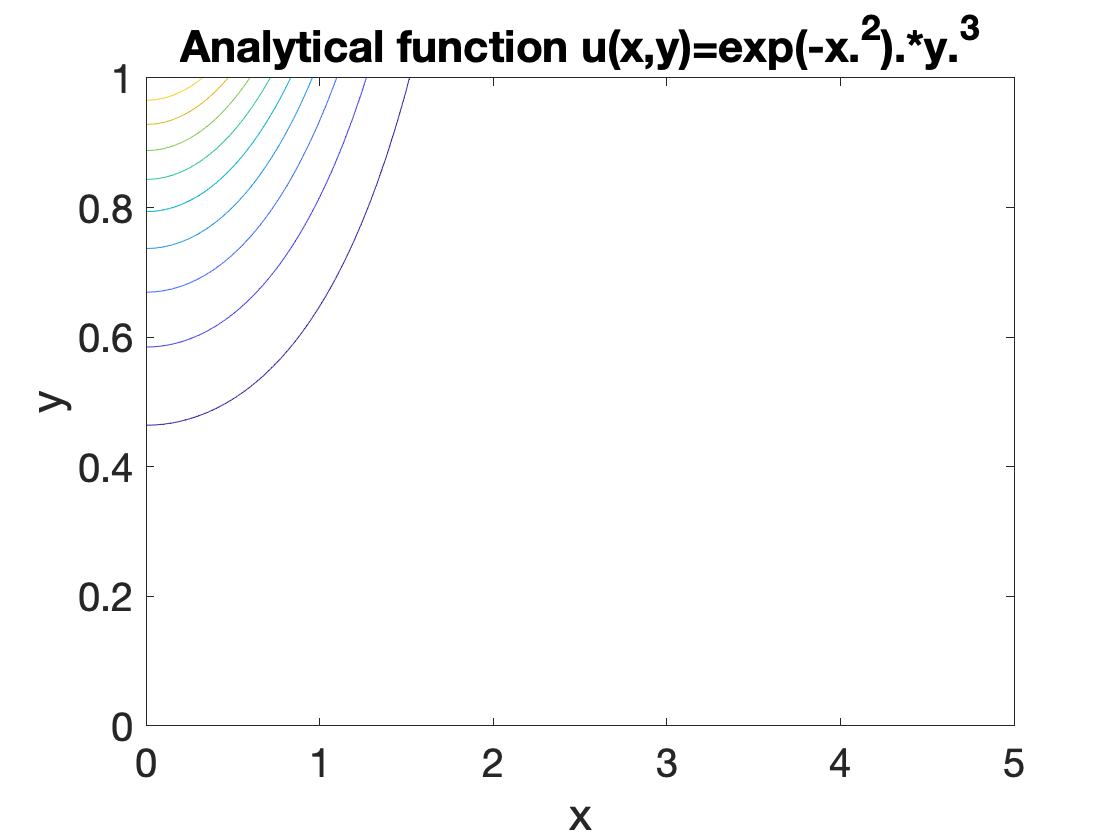

u=@(x,y)exp(-x.^2).*y.^3;
ux=@(x,y) -2.*x.*exp(-x.^2).*y.^3;
uy=@(x,y) exp(-x.^2).*3.*y.^2;
uxplusuy=@(x,y) y.*y.*exp(-x.^2).*(3-2.*x.*y);
xi=linspace(0,5,Nx);
yi=linspace(0,1,Ny);
[Xi,Yi]=meshgrid(xi,yi);
hold off
contour(Xi,Yi,u(Xi,Yi))
xlabel('x');ylabel('y')
title('Analytical function u(x,y)=exp(-x.^2).*y.^3')

Apply the derivative matrix on every row of the 2d [u] matrix

uij=u(Xi,Yi);
% Perform Matrix - Matrix multiplication to calculate derivative in y direction.  No need to transpose because data in the uij matrix is already in the right structure. 
dyuij=Derivy*uij;

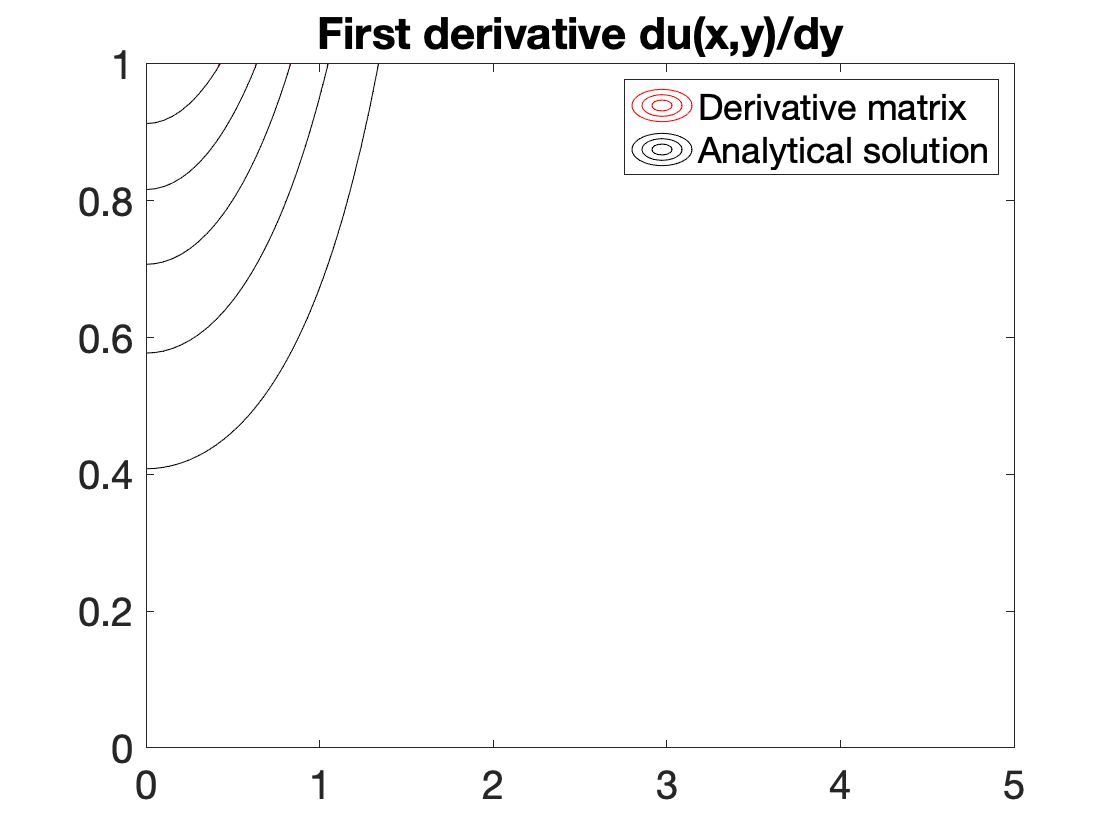

contour(Xi,Yi,dyuij,'r-')
hold on
contour(Xi,Yi,uy(Xi,Yi),'ko')
hold off
legend('Derivative matrix','Analytical solution')
title("First derivative du(x,y)/dy")

In the plot above, the contour lines of the analytical $\partial u/\partial y$ coincide with the contour lines of the approximate derivative.  So the derivative matrix is OK. 

Now we will construct the Derivative matrix where $u(x,y)$ is arranged as a column vector $\{u\}$.  You should be able to calculate the derivative of $\{u\}$ by just performing the matrix vector multiplication


$$\{u_y\}=[D_y]\{u\}$$


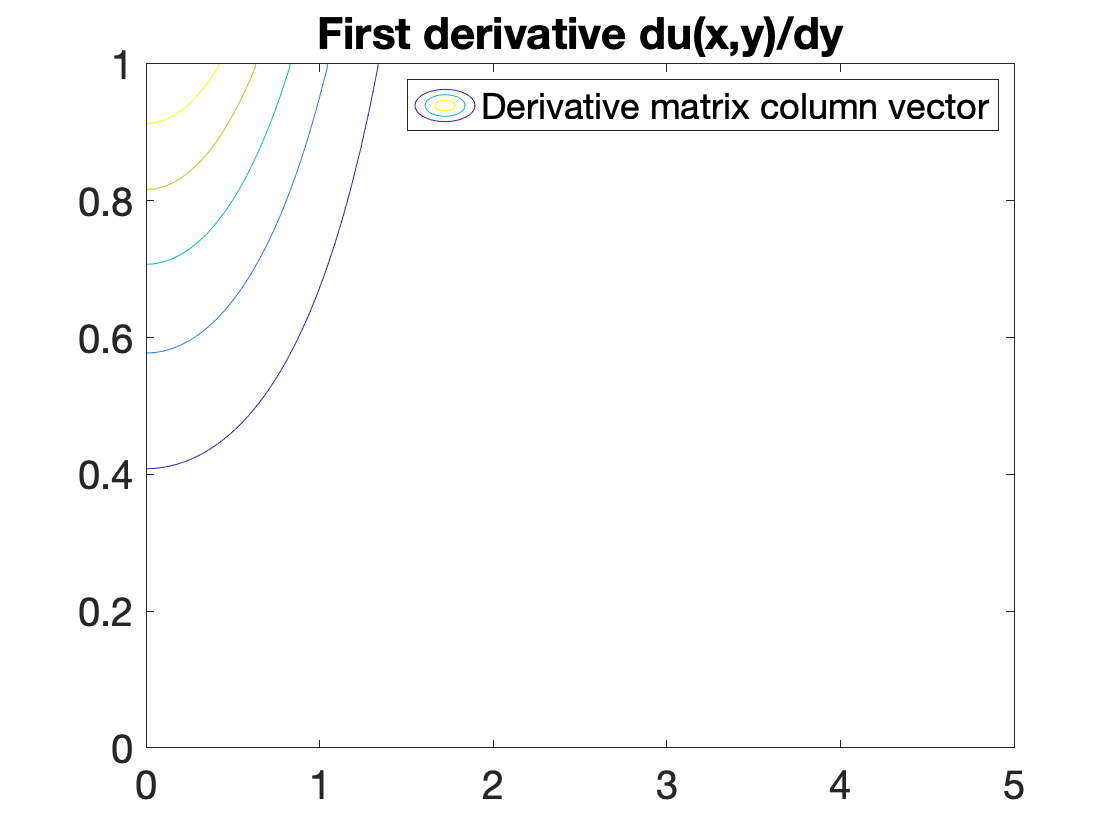

Derivy2D=kron(Derivy,eye(Nx));
uynum=Derivy2D*reshape(transpose(uij),[Ny*Nx 1]);
contour(Xi,Yi,reshape(uynum,Nx,Ny)');
legend('Derivative matrix column vector')
title("First derivative du(x,y)/dy")

Now to calculate the x derivative matrix

b=zeros(Nx,1);
b(1)=-2;
b(end)=2;

a=-ones(Nx-1,1);
a(end)=-2;

c=ones(Nx-1,1);
c(1)=2;
Deltax=xi(2)-xi(1);
Derivx=(diag(a,-1)+diag(b)+diag(c,1))/(2*Deltax);

Derivx2D=kron(eye(Ny),Derivx);

Now use the x and y derivative matrices to calculate $\frac{\partial u}{\partial x}+\frac{\partial u}{\partial y}$

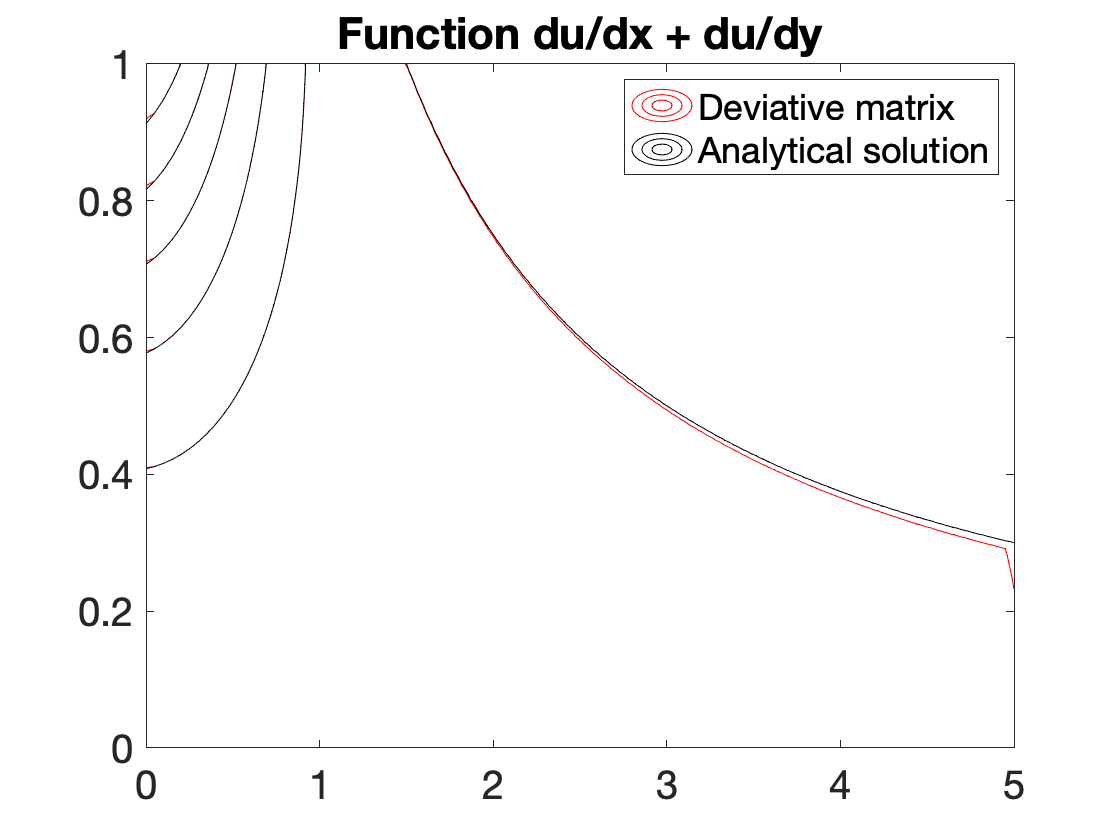

uxynum=(Derivx2D+Derivy2D)*reshape(transpose(uij),[Ny*Nx 1]);
figure
contour(Xi,Yi,reshape(uxynum,Nx,Ny)','r-')
hold on
contour(Xi,Yi,uxplusuy(Xi,Yi),'k-');
legend('Deviative matrix','Analytical solution')
title("Function du/dx + du/dy")

MatrixToSolve=(Derivx2D+Derivy2D);
rhs=reshape(uxplusuy(Xi,Yi)',[Nx*Ny 1]);
%Boundary condition  at x=0
for j=1:Ny    
    MatrixToSolve((j-1)*Nx+1,:)=0.0;
    MatrixToSolve((j-1)*Nx+1,(j-1)*Nx+1)=1.0;
    rhs((j-1)*Nx+1)=yi(j).^3;
end

%Boundary condition  at y=0
for i=1:Nx    
    MatrixToSolve(i,:)=0.0;
    MatrixToSolve(i,i)=1.0;
    rhs(i)=0;
end

unumeric=linsolve(MatrixToSolve,rhs);

Now plot the solution and compare with the "real" $u(x,y)=y^3e^{-x^2}$.

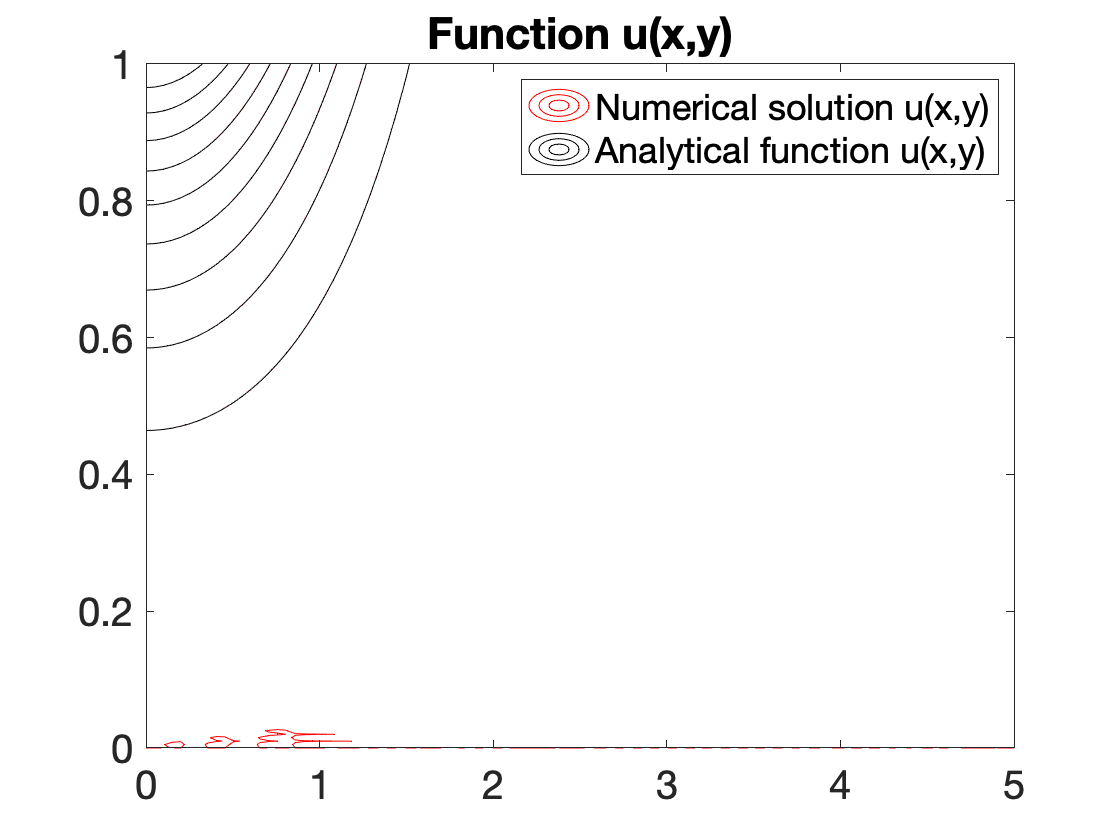

figure
unumericmatrix=reshape(unumeric,Nx,Ny)';
contour(Xi,Yi,unumericmatrix,'r-');
hold on
contour(Xi,Yi,u(Xi,Yi),'k-');
legend("Numerical solution u(x,y)", "Analytical function u(x,y)")
title("Function u(x,y)")